clc; clearvars;

%% -------------------------
% Inputs
%% -------------------------
elev_angles_deg = 5:1:90;   % sweep from 5° to 90°
link_margin_dB = zeros(size(elev_angles_deg));  % to store results
range_km_arr = zeros(size(elev_angles_deg));
rec_power_dBW_arr = zeros(size(elev_angles_deg));
SNR_dB_arr = zeros(size(elev_angles_deg));
CNo_dBHz_arr = zeros(size(elev_angles_deg));
EbN0_dB_arr = zeros(size(elev_angles_deg));

altitude_km = 500;            % [km]
freq_mhz = 437;               % [MHz]

% CubeSat TX
tx_pwr_Watt = 1;              % [W]
tx_line_losses_dB = 1;        % [dB] TX cable/connector/filter losses
ant_gain_dBi = 0;             % [dBi] CubeSat antenna gain

% Path / propagation losses
sat_pointing_loss_dB = 0;     % [dB]
polarization_loss_dB = 0;     % [dB]
atm_attenuation_dB = 0;       % [dB]

% Ground Station RX
gs_ant_gain_dBi = 15;         % [dBi]
gs_pointing_loss_dB = 0.5;    % [dB]
gs_line_loss_dB = 1;          % [dB] RX cable/connector/filter losses
eff_noise_temp_K = 300;       % [K] system noise temperature

% Data link
data_rate_bps = 1000;         % [bps]
B_noise_Hz = 20e3;            % [Hz] receiver filter bandwidth
modulation_method = "BPSK";
EbN0_threshold_dB = 9.6;      % [dB] for target BER

%% -------------------------
% Derived parameters
%% -------------------------
% Transmit power in dBW
tx_pwr_dBW = 10*log10(tx_pwr_Watt);

% Satellite EIRP
sat_EIRP_dBW = tx_pwr_dBW - tx_line_losses_dB + ant_gain_dBi;

Re_km = 6371;  % Earth radius [km]

for i = 1:length(elev_angles_deg)
    elev_angle_degrees = elev_angles_deg(i);
    
    % Slant range
    range_km = sqrt((Re_km + altitude_km)^2 - (Re_km*cosd(elev_angle_degrees))^2);
    range_m = range_km * 1e3;
    range_km_arr(i) = range_km;  % store

    % Free-space path loss
    lambda_m = 3e8 / (freq_mhz*1e6);
    free_space_loss_dB = 20*log10(4*pi*range_m / lambda_m);

    % Total path loss
    total_path_loss_dB = free_space_loss_dB + sat_pointing_loss_dB + ...
                         polarization_loss_dB + atm_attenuation_dB;

    % Received power (classic)
    rec_power_dBW = sat_EIRP_dBW - total_path_loss_dB + gs_ant_gain_dBi ...
                    - gs_pointing_loss_dB - gs_line_loss_dB;
    rec_power_dBW_arr(i) = rec_power_dBW;

    % Noise power (constant)
    k = 1.380649e-23;
    N_W = k * eff_noise_temp_K * B_noise_Hz;
    N_dBW = 10*log10(N_W);

    % SNR
    SNR_dB = rec_power_dBW - N_dBW;
    SNR_dB_arr(i) = SNR_dB;

    % G/T method
    G_rx_eff_dBi = gs_ant_gain_dBi - gs_pointing_loss_dB - gs_line_loss_dB;
    gs_figure_of_merit = G_rx_eff_dBi - 10*log10(eff_noise_temp_K);
    CNo_dBHz = sat_EIRP_dBW - total_path_loss_dB + gs_figure_of_merit + 228.6;
    CNo_dBHz_arr(i) = CNo_dBHz;

    EbN0_dB = CNo_dBHz - 10*log10(data_rate_bps);
    EbN0_dB_arr(i) = EbN0_dB;

    % Link margin
    link_margin_dB(i) = EbN0_dB - EbN0_threshold_dB;
end

% Simple display
disp('Elevation (deg) | Range (km) | Rec Power (dBW) | SNR (dB) | C/N0 (dBHz) | Eb/N0 (dB) | Link Margin (dB)');

Elevation (deg) | Range (km) | Rec Power (dBW) | SNR (dB) | C/N0 (dBHz) | Eb/N0 (dB) | Link Margin (dB)


for i = 1:length(elev_angles_deg)
    fprintf('%6.1f          | %8.2f    | %10.2f       | %6.2f  | %10.2f   | %6.2f    | %6.2f\n', ...
        elev_angles_deg(i), range_km_arr(i), rec_power_dBW_arr(i), ...
        SNR_dB_arr(i), CNo_dBHz_arr(i), EbN0_dB_arr(i), link_margin_dB(i));
end

   5.0          |  2632.36    |    -141.16       |  19.66  |      62.67   |  32.67    |  23.07
   6.0          |  2657.91    |    -141.24       |  19.58  |      62.59   |  32.59    |  22.99
   7.0          |  2687.72    |    -141.34       |  19.48  |      62.49   |  32.49    |  22.89
   8.0          |  2721.61    |    -141.45       |  19.37  |      62.38   |  32.38    |  22.78
   9.0          |  2759.40    |    -141.57       |  19.25  |      62.26   |  32.26    |  22.66
  10.0          |  2800.88    |    -141.70       |  19.12  |      62.13   |  32.13    |  22.53
  11.0          |  2845.84    |    -141.84       |  18.98  |      61.99   |  31.99    |  22.39
  12.0          |  2894.06    |    -141.98       |  18.84  |      61.85   |  31.85    |  22.25
  13.0          |  2945.33    |    -142.13       |  18.68  |      61.69   |  31.69    |  22.09
  14.0          |  2999.43    |    -142.29       |  18.53  |      61.54   |  31.54    |  21.94
  15.0          |  3056.14    |    -142.45       |

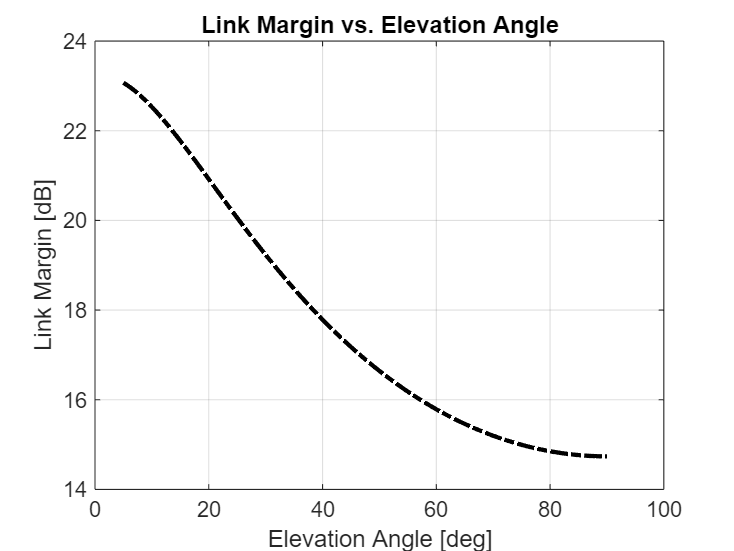


figure;
plot(elev_angles_deg, link_margin_dB, 'black-.', 'LineWidth', 2, 'MarkerSize', 5);
xlabel('Elevation Angle [deg]');
ylabel('Link Margin [dB]');
title('Link Margin vs. Elevation Angle');
grid on;